# Scratch pad

Random work ideas. 

## Cepstral 13 features

Fitted models to the cepstral feature set with 13 features. Cubic SVM had the highest accuracy of 84.5% (10-fold cross-validation). I would like to know the trends of the correctly and misclassified predictions. 

% Find base directory
basedir = fileparts(pwd);

% Model data
modeldir = "data/Models";

% Data file
modelfile = "SNR10Cepstral13SVMCubic.mat";

% Load data
load(fullfile(basedir,modeldir,modelfile))
f = (1:13)';

Extract predicted classes from model. 

% Extract predicted classes
yfit = logical(mdlCep13.predictFcn(xfeatures13));

% Accuracy score (in-sample)
mean(yfit == xfeatures13.contaminated)

ans = 0.8897


% Clean signal features
xsignal = xfeatures13(xfeatures13.contaminated == false,1:end-1);
xsignalpred = yfit(xfeatures13.contaminated == false);

% Contaminated features
xcontaminated = xfeatures13(xfeatures13.contaminated == true,1:end-1);
xcontaminatedpred = yfit(xfeatures13.contaminated == true);

## Plots

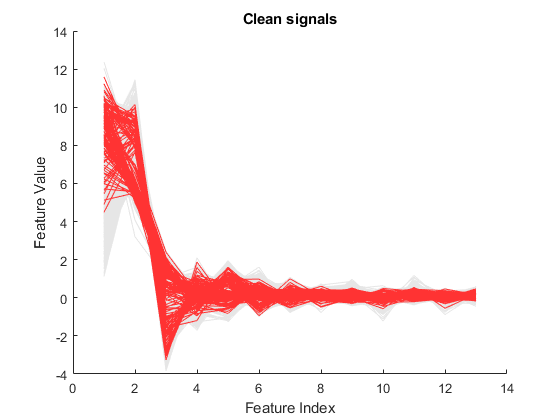

% Clean signals
plotFeaturesClass(xsignal,xfeatures13.contaminated(xfeatures13.contaminated == false),xsignalpred)
title("Clean signals")

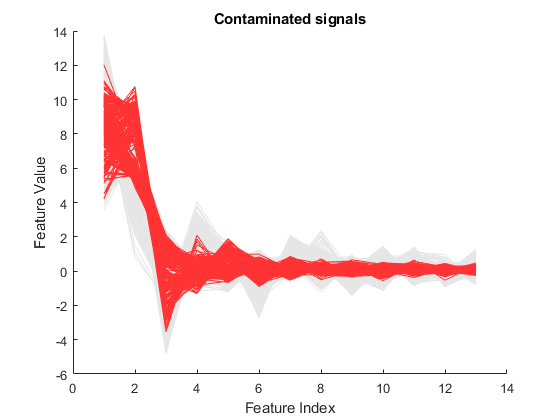


% Contaminated signals
plotFeaturesClass(xcontaminated,xfeatures13.contaminated(xfeatures13.contaminated == true),xcontaminatedpred)
title("Contaminated signals")

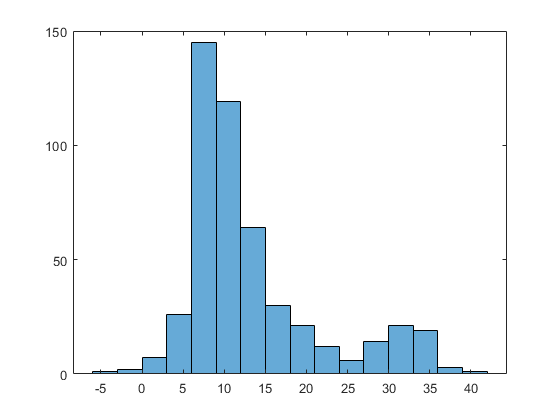

% Look at histrogram of SNR for contaminated signals misclassified
histogram(blockSNRdB(xfeatures13.contaminated == 1 & xfeatures13.contaminated ~= yfit))

% Count the number of misclassified blocks with SNR > 20
sum(blockSNRdB(xfeatures13.contaminated == 1 & xfeatures13.contaminated ~= yfit) >= 20)

ans = 82